## Ali Saeizadeh - 810196477

## Section 1

### 1.

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab5'
clear all; clc; close all;
dcl_init;
modulation = 'qam';             
k = 4;                      
M = 2^k;  
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k)

b_tx =      0     0     1     0
     1     1     1     1
     0     0     1     1
     0     0     1     1
     0     1     1     0
     0     1     1     1
     0     1     0     1
     0     0     1     0
     0     0     0     0
     1     0     0     1


### 2.

flg_gray_encode = 1

flg_gray_encode = 1

if(flg_gray_encode == 1)
    b_code = gray_code(k)    
else
    b_code = non_code(k) 
end 

b_code =      0     0     0     0
     0     0     0     1
     0     0     1     1
     0     0     1     0
     0     1     1     0
     0     1     1     1
     0     1     0     1
     0     1     0     0
     1     1     0     0
     1     1     0     1



sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
sym_idx

sym_idx =      4
    11
     3
     3
     5
     6
     7
     4
     1
    15


[cons, Es_avg] = constellation(M, modulation)

cons =   -0.9487 - 0.9487i
  -0.3162 - 0.9487i
   0.3162 - 0.9487i
   0.9487 - 0.9487i
   0.9487 - 0.3162i
   0.3162 - 0.3162i
  -0.3162 - 0.3162i
  -0.9487 - 0.3162i
  -0.9487 + 0.3162i
  -0.3162 + 0.3162i


Es_avg = 1

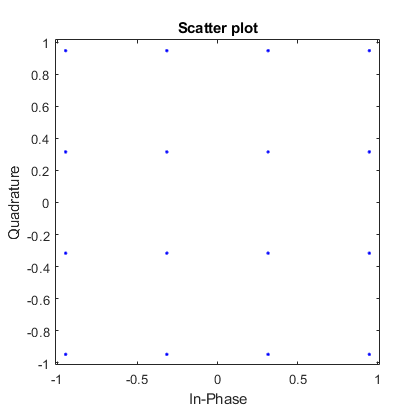

scatterplot(cons)

mod_sym = zeros(size(sym_idx));
for i=1:size(sym_idx,1)
    mod_sym(i,1) = cons(sym_idx(i,1));
end
mod_sym

mod_sym =    0.9487 - 0.9487i
   0.3162 + 0.3162i
   0.3162 - 0.9487i
   0.3162 - 0.9487i
   0.9487 - 0.3162i
   0.3162 - 0.3162i
  -0.3162 - 0.3162i
   0.9487 - 0.9487i
  -0.9487 - 0.9487i
  -0.3162 + 0.9487i


### 3

pulse_shape_mode = 'kron'

pulse_shape_mode = 'kron'

[tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);

tx_smpl_delayed = [zeros(chnl_delay_in_smpl,1); tx_smpl];
rx_smpl = tx_smpl_delayed .* exp(1i*chnl_phase_offset);

Eb =  Es_avg/log2(M) 

Eb = 0.2500

EbNo = db2pow(snr_max)

EbNo = 10

var_noise = (Eb ./ EbNo)

var_noise = 0.0250

mean_noise = 0

mean_noise = 0

noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise

noise_smpl =    0.1287 + 0.1471i
  -0.0326 + 0.1148i
  -0.0086 + 0.0394i
  -0.0334 - 0.0449i
  -0.1365 + 0.0527i
   0.1965 - 0.0254i
   0.0145 - 0.0828i
   0.0088 + 0.0508i
   0.0361 + 0.1675i
   0.0826 + 0.0839i


rx_smpl_noise = rx_smpl + noise_smpl

rx_smpl_noise =    0.1287 + 0.1471i
   0.1104 - 0.0282i
   0.2774 - 0.2466i
   0.3957 - 0.4739i
   0.4356 - 0.5193i
   0.6256 - 0.4544i
   0.3006 - 0.3688i
   0.1518 - 0.0922i
   0.0361 + 0.1675i
   0.1303 + 0.1316i


rx_smpl_eq = rx_smpl_noise(chnl_delay_in_smpl + 1 : end);
modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode

modulation = 'qam'

M = 16

fs = 10000000

smpl_per_symbl = 8

pulse_name = 'triangular'

rx_mode = 'matched_filter'

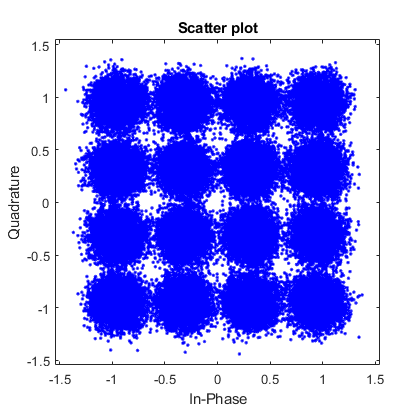

[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
scatterplot(rx_sym)

det_bit = b_code(det_sym_idx,:)

det_bit =      0     0     1     0
     1     1     1     1
     0     0     1     1
     0     0     1     1
     0     1     1     0
     0     1     1     1
     0     1     0     1
     0     0     1     0
     0     0     0     0
     1     0     0     1


ser = sum(det_sym_idx ~= sym_idx)/length(sym_idx)

ser = 0.0069

ber = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2))

ber = 0.0017

serPSK = zeros(size(snr_db));
berPSK = zeros(size(snr_db));
for i = 0:1:3
    Eb =  Es_avg/log2(M);
    EbNo = db2pow(i);
    var_noise = (Eb ./ EbNo);
    mean_noise = 0;
    noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
    rx_smpl_noise = rx_smpl + noise_smpl;
    rx_smpl_eq = rx_smpl_noise(chnl_delay_in_smpl + 1 : end);
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
    det_bit = b_code(det_sym_idx,:);
    serPSK(i + 1) = sum(det_sym_idx ~= sym_idx)/length(sym_idx);
    berPSK(i + 1) = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2));
end


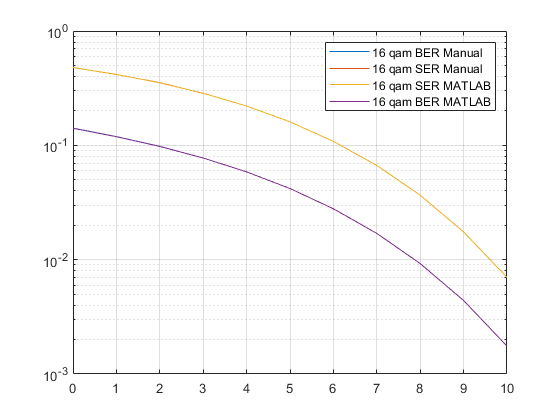

figure
[berPSK_matlab, serPSK_matlab] = berawgn(snr_db,modulation,M);
semilogy(snr_db,berPSK)
hold on
semilogy(snr_db,serPSK)
hold on
semilogy(snr_db,serPSK_matlab)
hold on
semilogy(snr_db,berPSK_matlab)
legend(sprintf('%d %s BER Manual',M,modulation),sprintf('%d %s SER Manual',M,modulation), sprintf('%d %s SER MATLAB',M,modulation), sprintf('%d %s BER MATLAB',M,modulation))
grid on

figure